## Self-positioning using aircraft signals and reference sensors

Okay, let's start doing the real heavy lifting since Python couldn't handle some few millions of lines

% Load data
clear; clc;
% Helper functions' path
addpath('geodesy');
addpath('src')

% Note that for training we have results as well
training = false;

if training
    DIRECTORY_NUM = '1';
    MEASUREMENTS_DIR = sprintf('../datasets/round_1/%s/training_%s_category_1', DIRECTORY_NUM, DIRECTORY_NUM);
    RESULTS_DIR = sprintf('../datasets/round_1/%s/training_%s_category_1_result', DIRECTORY_NUM, DIRECTORY_NUM);

    % We have 2 sets: measurements and results (to compare our approach to)
    MEASUREMENTS_CSV = sprintf('training_%s_category_1.csv', DIRECTORY_NUM);
    SENSORS_CSV = 'sensors.csv';
    RESULTS_CSV = 'training_{}_category_1_result.csv';
    
    BAD_SENSORS = [19]
else
    MEASUREMENTS_DIR = '../datasets/round_1';
    RESULTS_DIR = '';

    % We have 2 sets: measurements and results (to compare our approach to)
    MEASUREMENTS_CSV = 'round1_competition.csv';
    SENSORS_CSV = 'sensors.csv';
    RESULTS_CSV = '';
    
    BAD_SENSORS = [19];
end

CACHE = 'workspace.mat';

Start the parallel pool (to speed up some computations)

if isempty(gcp('nocreate'))
    parpool('local', 4, 'IdleTimeout', 120);
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


Load data (first check if it's in the cache, otherwise it's gonna take long)

if isfile(sprintf('%s/%s', MEASUREMENTS_DIR, CACHE))
    load(sprintf('%s/%s', MEASUREMENTS_DIR, CACHE), 'ddoa', 'aircraft', 'sensors');
else
    f = true;
    [aircraft, sensors] = loadData(MEASUREMENTS_DIR, MEASUREMENTS_CSV, SENSORS_CSV, f);
    ddoa = getddoa(aircraft);
    save(sprintf('%s/%s', MEASUREMENTS_DIR, CACHE), 'ddoa', 'aircraft', 'sensors');
end

% Speed of light is 299792458 m/s
c = 299792458/1.0003;
ddoa.ddoam = ddoa.ddoa * 1e-9 * c;

backup_sensors = sensors; backup_aircraft = aircraft; backup_ddoa = ddoa;

Restoration

% User this to restore everything
sensors = backup_sensors;
aircraft = backup_aircraft;
ddoa = backup_ddoa;

## Computing cartesian distances

For aircrafts

% Computing cartesian coordinates
xyz = llh2ecef([aircraft.latitude, aircraft.longitude, aircraft.geoAltitude]);
aircraft.x = xyz(:,1);
aircraft.y = xyz(:,2);
aircraft.z = xyz(:,3);

% Let's obtain the coordinates of the aircraft measurements and also relate them
% with the average positon
center = [(quantile(aircraft.x,0.01) + quantile(aircraft.x,0.99))/2, ...
          (quantile(aircraft.y,0.01) + quantile(aircraft.y,0.99))/2, ...
          (quantile(aircraft.z,0.01) + quantile(aircraft.z,0.99))/2];
      
aircraft.x = aircraft.x - center(1);
aircraft.y = aircraft.y - center(2);
aircraft.z = aircraft.z - center(3);

For sensors

% For reproducible results
rng('default');

% Let's only keep sensors that appear on the measurements
keep = zeros(size(sensors,1),1) == 1;
for ii = 1:size(sensors,1)
    if any(ddoa.s1 == sensors.serial(ii)) || any(ddoa.s2 == sensors.serial(ii))
        keep(ii) = true;
    end
end

sensors = sensors(keep,:);

% Let's also compute the cartesian coordinates
xyz = llh2ecef([sensors.latitude, sensors.longitude, sensors.height]);
sensors.x = xyz(:,1) - center(1);
sensors.y = xyz(:,2) - center(2);
sensors.z = xyz(:,3) - center(3);

% One of the sensors is off so we can take it out
sensors(BAD_SENSORS,:) = [];

% We can compute the errors between the measured and expected TDOAs
maskddoa = ismember(ddoa.s1, sensors.serial, 'rows') & ismember(ddoa.s2, sensors.serial, 'rows');
ddoa = ddoa(maskddoa,:);

[~,acId] = ismember(ddoa.id, aircraft.id, 'rows');
[~,s1Id] = ismember(ddoa.s1, sensors.serial, 'rows');
[~,s2Id] = ismember(ddoa.s2, sensors.serial, 'rows');

acd = table2array(aircraft(acId,{'x', 'y', 'z'}));
s1d = table2array(sensors(s1Id,{'x', 'y', 'z'}));
s2d = table2array(sensors(s2Id,{'x', 'y', 'z'}));

% Computation of TDOAs
d1 = ecef_distance(acd, s1d);
d2 = ecef_distance(acd, s2d);

exp = d1 - d2;
ddoa.exp = exp;
ddoa.err = exp - ddoa.ddoam;

## Removing outliers

Some of the measurements are completely off and break the optimization.

Light travels almost 300.000 km per second.

A TDOA error of 30.000 km is not really possible (it's almost the earth circumference) so those measurements should be broken

maskerr = ddoa.err > quantile(ddoa.err,0.05) & ddoa.err < quantile(ddoa.err,0.95);
ddoa = ddoa(maskerr,:);

%%% Removing unnecessary aircrafts
unique_ids = unique(ddoa.id);
maskair = ismember(aircraft.id,unique_ids);
aircraft = aircraft(maskair,:);

% First we need to cleanup the aircrafts
% We can get the time and distance the aircraft moved while it was seen by the
% system
% Then we remove all the sensors that have wrong measurements
aircraft_list = unique(aircraft.aircraft);

max_dist = zeros(length(aircraft_list),1);
max_time = zeros(length(aircraft_list),1);
for ii = 1:length(aircraft_list)
    acId = aircraft_list(ii);
    aircraftPath = aircraft(aircraft.aircraft == acId, :);
    
    if height(aircraftPath) > 1
        max_dist(ii) = norm(table2array(aircraftPath(end,{'x','y','z'})) - table2array(aircraftPath(1,{'x','y','z'})))/1000;
        max_time(ii) = norm(table2array(aircraftPath(end,{'timeAtServer'})) - table2array(aircraftPath(1,{'timeAtServer'})));
    else
        max_dist(ii) = 0;
        max_time(ii) = 0;
    end
end

g = max_dist ~= 0;
good_aircraft = aircraft_list(g);

% Filter aircraft
maskair = ismember(aircraft.aircraft,good_aircraft);
aircraft = aircraft(maskair,:);

% Filter ddoa
maskddoa = ismember(ddoa.id,aircraft.id);
ddoa = ddoa(maskddoa,:);

## Optimization approaches (with offset)

In this one, we will use all sensors but one and optimize the position (imitating a user)

### Precomputing the offsets

The observation is that offsets remain 'constant' throughtout time, so no need to divide by aircraft or time

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Linear least squares    
% We start with the C matrix
C = zeros(height(ddoa), height(sensors));
for index = 1:height(sensors)
    s = sensors.serial(index);
    mask_positive = ddoa.s1 == s;
    mask_negative = ddoa.s2 == s;
    
    C(mask_positive, index) = 1;
    C(mask_negative, index) = -1;
end

% Now the d vector
d = -ddoa.err;

% We set the lower and upper bounds
sigma = std(ddoa.err);
% lb = [-1e-7;-5*sigma.*ones(height(sensors)-1,1)];
% ub = [ 1e-7; 5*sigma.*ones(height(sensors)-1,1)];
lb = [-1e-7;-inf.*ones(height(sensors)-1,1)];
ub = [ 1e-7; inf.*ones(height(sensors)-1,1)];

offsets = lsqlin(C,d,[],[],[],[],lb,ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sensors.offsets = offsets;

% Optimization by fraction and sensor
% Ok, so let's set up the fractions and optimize per each one of them
% Things, that are interesting to store:
% results: (x,y,z,o,flag) 5xN_sxN_f
% time: N_sxN_f
% measurement_count: N_sxN_f (Counting how many measurements for optimization)
% Afterwards: save results, time, sensors, center

% Our hard earned results will thank it
saveall = true;

% Our main results
fractions = fliplr(10.^(linspace(-1,-1,1)));
result = zeros(height(sensors), 5, length(fractions)); % x, y, z, offset & flag
time = zeros(height(sensors), length(fractions));
measurement_count = zeros(height(sensors), length(fractions));
density = zeros(height(sensors),1);

% Optimization options
options = optimoptions('fminunc','Display','off','Algorithm','trust-region',...
                       'SpecifyObjectiveGradient',true,'UseParallel',true,'MaxIterations',1000,...
                       'MaxFunctionEvaluations', 300000, 'StepTolerance',1e-15, 'OptimalityTolerance',1e-15);

% Loop parameters
numIter = 1; % Iterations per fraction and sensor
num_ref = 5; % Max number of reference sensors to use

tic;
for ii = 1:height(sensors)
    %% Data preparation
    sensor = sensors(ii,:);
    
%     fprintf('Starting with sensor: %d\n',sensor.serial);

    %% Selecting by policy
    mask = (ddoa.s1 == sensor.serial) | (ddoa.s2 == sensor.serial);
    
    %% TODO: Move the selection policy to a function
    % For now, we will use the most common sensors as ground
    ddoa_sensor_count = grpstats(ddoa(mask,:),{'s1','s2'});
    ddoa_sensor_count = sortrows(ddoa_sensor_count,'GroupCount','descend');
    Ng = min([height(ddoa_sensor_count), num_ref]);
    
    indices = zeros(Ng,1);
    for jj = 1:Ng
        if ddoa_sensor_count.s1(jj) == sensor.serial
            indices(jj) = find(sensors.serial == ddoa_sensor_count.s2(jj));
        else
            indices(jj) = find(sensors.serial == ddoa_sensor_count.s1(jj));
        end
    end
    ground = sensors(indices,:);
    
    % Let's filter the data
    mask_s = ismember(ddoa.s1, sensor.serial, 'rows') | ismember(ddoa.s2, sensor.serial, 'rows');
    mask_g = ismember(ddoa.s1, ground.serial, 'rows') | ismember(ddoa.s2, ground.serial, 'rows');
    mask_s = mask_s & mask_g;
    data = ddoa(mask_s,:);
    
%     % Filter the aircraft table too
%     maskair = ismember(aircraft.id,unique(data.id));
%     ac = aircraft(maskair,:);
    
    % We need the mean positions
    unique_id = unique(data.id);
    [~,idx,~] = intersect(aircraft.id,unique_id);
    ac = aircraft(idx,:);
    
    p0.x = mean(aircraft.x(idx));
    p0.y = mean(aircraft.y(idx));
    p0.z = mean(aircraft.z(idx));
    
    % Initial position
    x0 = [p0.x; p0.y; p0.z; 2*5*sigma*rand(1)-5*sigma];
    
    % Density estimation
    max_lat = max([sensor.latitude;ground.latitude]);
    min_lat = min([sensor.latitude;ground.latitude]);
    max_lon = max([sensor.longitude;ground.longitude]);
    min_lon = min([sensor.longitude;ground.longitude]);
    
    density(ii) = areaquad(min_lat,min_lon,max_lat,max_lon,referenceSphere('earth','km'))/(height(ground)+1);
    
    for f = 1:length(fractions)
        % Extract the current fraction
        fraction = fractions(f);
%         fprintf('Optimizing for fraction: %f... ',fraction);

        %% Let's filter data
        indices = randsample(1:height(data),round(fraction*height(data)));
        dt = data(sort(indices),:);
%         index = randi([0,height(ddoa)-ceil(height(ddoa)*fraction)]) + 1;
%         dt = ddoa(index:index+floor(height(ddoa)*fraction),:);
        
        %% Now that we have the offsets let's start with the real optimization
        fun = @(x) minimizeroffset(x(1), x(2), x(3), x(4), sensor.serial, ac, dt, ground(:,{'x','y','z','offsets','serial'}));
               
        tmp_result = zeros(numIter,5);
        tmp_time = zeros(numIter,1);
        for jj = 1:numIter
            %% Let's have some fun
            tic;
            try
                [position,fval,flag] = fminunc(fun,x0,options);
            catch
                warning('Could not optimize position');
                fval = 0;
            end
            % Store statistics
            tmp_time(jj) = toc;
            
            % Check whether output was successful
            if fval ~= 0
                tmp_result(jj,:) = [position; 1]';
            else
                tmp_result(jj,:) = [0.0 0.0 0.0 0.0 0];
            end
    %         fprintf('Finished.\n')
        end
        
        % Collect all statistics
        result(ii,:,f) = mean(tmp_result,1);
        time(ii,f) = mean(tmp_time);
        measurement_count(ii,f) = height(dt);
        
    end
%     fprintf('Finished with sensor: %d\n-----------\n',sensor.serial);
end

if saveall
    save(sprintf('results/%s_fractions_%.2f_%.2f.mat',datestr(datetime,30),min(fractions),max(fractions)),...
         'result','time','measurement_count','fractions','sensors','center','density');
end

load("results/20201019T105030_fractions_0.00_1.00.mat");
load('b.mat');

% Let's calculate errors
senval = table2array(sensors(:,{'x','y','z'}));

% Results
rmse = zeros(length(fractions),1);
rmse_2d = rmse;
dist3d = zeros(height(sensors),length(fractions));
dist = dist3d;

for ii = 1:length(fractions)
    resval = result(:,1:3,ii);
    
    % 3D error
    errors = resval(:,1:3) - senval;
    dist3d(:,ii) = sqrt(sum(errors.^2,2));
    
    rmse(ii) = sqrt(median(dist3d(:,ii).^2));
    
    % Compute the 2D distance
    unknownllh = ecef2llh(resval(:,1:3) + center);
    realposllh = table2array(sensors(:, {'latitude','longitude','height'}));
    
    dist(:,ii) = havdist(unknownllh, realposllh);
    rmse_2d(ii) = sqrt(median(dist(:,ii).^2));
end

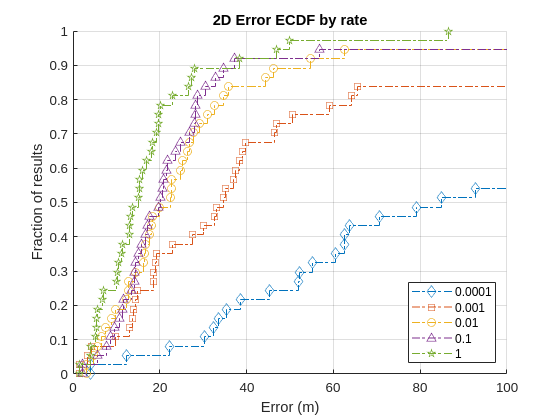

figure();
hold on; grid on;
flab = cell(ceil(length(fractions)/8),1);
styles = {'d-.', 's-.', 'o-.', '^-.', 'p-.'};
dist(:,end) = b;
k = 1;
for ii = 1:length(fractions)
    if mod(ii+2,3) == 0
        [f,y] = ecdf(dist(:,ii));
        stairs(y,f,styles{k});
        flab{k} = num2str(fractions(ii));
        k = k+1;
    end
end
legend(flab,'Location',"southeast");

title("2D Error ECDF by rate");
xlabel('Error (m)');
ylabel('Fraction of results');
xlim([0,100]);
hold off;

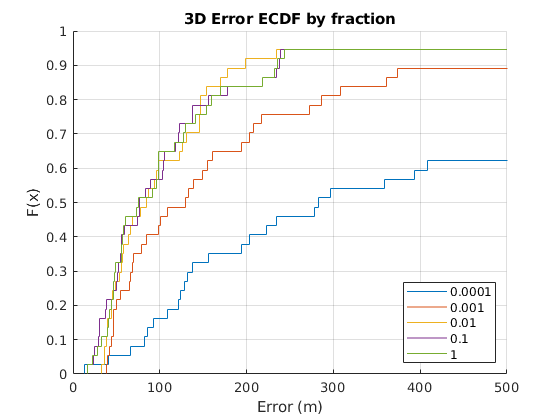

figure();
hold on; grid on;

for ii = 1:length(fractions)
    if mod(ii+2,3) == 0
        ecdf(dist3d(:,ii));
    end
end
legend(flab,'Location',"southeast");

xlabel('Error (m)');
title('3D Error ECDF by fraction');
xlim([0,500]);
hold off;

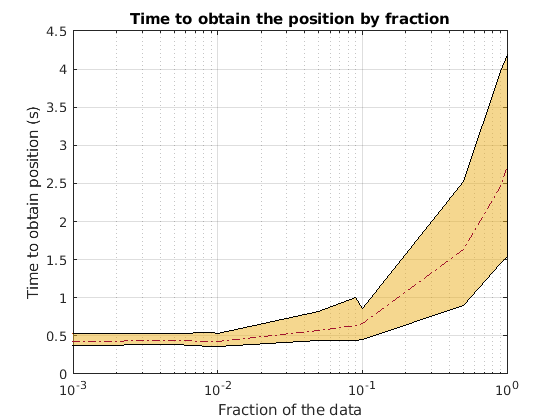

figure();
labels = cell(length(fractions),1);
q25 = zeros(1,length(fractions));
q50 = zeros(1,length(fractions));
q75 = zeros(1,length(fractions));
for ii = 1:length(fractions)
    labels{ii} = num2str(fractions(ii));
    q25(ii) = quantile(time(:,ii),0.25);
    q50(ii) = quantile(time(:,ii),0.50);
    q75(ii) = quantile(time(:,ii),0.75);
end

figure();
semilogx(fractions, q25,'Color',[0.8500, 0.3250, 0.0980],'LineStyle',"--");
hold on; grid on;
semilogx(fractions,q75,'Color',[0.8500, 0.3250, 0.0980],'LineStyle',"--");
f_flip = [fractions, fliplr(fractions)];
d_flip = [q25, fliplr(q75)];
h = fill(f_flip,d_flip,[0.9290, 0.6940, 0.1250]);
alpha(h,0.5);
semilogx(fractions,q50,'Color',[0.6350 0.0780 0.1840],'LineStyle',"-.");
xlim([1e-3,max(fractions)]);
title('Time to obtain the position by fraction');
xlabel('Fraction of the data');
ylabel('Time to obtain position (s)');
hold off;

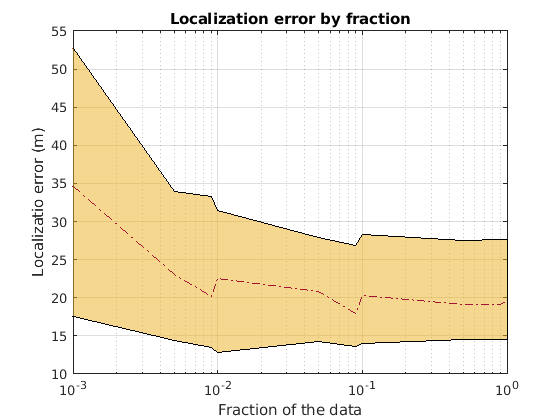

figure();
labels = cell(length(fractions),1);
q25 = zeros(1,length(fractions));
q50 = zeros(1,length(fractions));
q75 = zeros(1,length(fractions));
for ii = 1:length(fractions)
    labels{ii} = num2str(fractions(ii));
    q25(ii) = quantile(dist(:,ii),0.25);
    q50(ii) = quantile(dist(:,ii),0.50);
    q75(ii) = quantile(dist(:,ii),0.75);
end

figure();
semilogx(fractions, q25,'Color',[0.8500, 0.3250, 0.0980],'LineStyle',"--");
hold on; grid on;
semilogx(fractions,q75,'Color',[0.8500, 0.3250, 0.0980],'LineStyle',"--");
f_flip = [fractions, fliplr(fractions)];
d_flip = [q25, fliplr(q75)];
h = fill(f_flip,d_flip,[0.9290, 0.6940, 0.1250]);
alpha(h,0.5);
semilogx(fractions,q50,'Color',[0.6350 0.0780 0.1840],'LineStyle',"-.");
xlim([1e-3,max(fractions)]);
title('Localization error by fraction');
xlabel('Fraction of the data');
ylabel('Localizatio error (m)');
hold off;

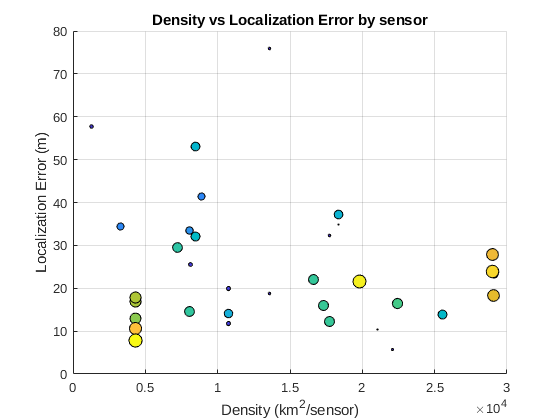

% Let's look at the density

distf1 = dist(:,end); % With all data
measf1 = measurement_count(:,end);
scatter(density,distf1,measf1/max(measf1)*100,measf1,'filled','MarkerEdgeColor',[0 0 0]); grid on;
xlabel('Density (km^2/sensor)');
ylabel('Localization Error (m)');
title('Density vs Localization Error by sensor');
ylim([0,80])

## Testing: Another time test

% Optimization by fraction and sensor
% Ok, so let's set up the fractions and optimize per each one of them
% Things, that are interesting to store:
% results: (x,y,z,o,flag) 5xN_sxN_f
% time: N_sxN_f
% measurement_count: N_sxN_f (Counting how many measurements for optimization)
% Afterwards: save results, time, sensors, center

% Our hard earned results will thank it
saveall = true;

% Our main results
% fractions = fliplr(10.^(linspace(-4,0,30)));
lims = [10, 8, 5, 3, 2];
fracs = [1e-2, 1e-3, 1e-4];
fractions = lims'*fracs;
fractions = fractions(:);
result = zeros(height(sensors), 5, length(fractions)); % x, y, z, offset & flag
time = zeros(height(sensors), length(fractions));
measurement_count = zeros(height(sensors), length(fractions));
density = zeros(height(sensors),1);

% Optimization options
options = optimoptions('fminunc','Display','off','Algorithm','trust-region',...
                       'SpecifyObjectiveGradient',true,'UseParallel',true,'MaxIterations',1000,...
                       'MaxFunctionEvaluations', 300000, 'StepTolerance',1e-15, 'OptimalityTolerance',1e-15);

% Loop parameters
numIter = 5; % Iterations per fraction and sensor
num_ref = 5; % Max number of reference sensors to use

tic;
for ii = 1:height(sensors)
    %% Data preparation
    sensor = sensors(ii,:);
    
%     fprintf('Starting with sensor: %d\n',sensor.serial);

    %% Selecting by policy
    mask = (ddoa.s1 == sensor.serial) | (ddoa.s2 == sensor.serial);
    
    %% TODO: Move the selection policy to a function
    % For now, we will use the most common sensors as ground
    ddoa_sensor_count = grpstats(ddoa(mask,:),{'s1','s2'});
    ddoa_sensor_count = sortrows(ddoa_sensor_count,'GroupCount','descend');
    Ng = min([height(ddoa_sensor_count), num_ref]);
    
    indices = zeros(Ng,1);
    for jj = 1:Ng
        if ddoa_sensor_count.s1(jj) == sensor.serial
            indices(jj) = find(sensors.serial == ddoa_sensor_count.s2(jj));
        else
            indices(jj) = find(sensors.serial == ddoa_sensor_count.s1(jj));
        end
    end
    ground = sensors(indices,:);
    
    % Let's filter the data
    mask_s = ismember(ddoa.s1, sensor.serial, 'rows') | ismember(ddoa.s2, sensor.serial, 'rows');
    mask_g = ismember(ddoa.s1, ground.serial, 'rows') | ismember(ddoa.s2, ground.serial, 'rows');
    mask_s = mask_s & mask_g;
    data = ddoa(mask_s,:);
    
%     % Filter the aircraft table too
%     maskair = ismember(aircraft.id,unique(data.id));
%     ac = aircraft(maskair,:);
    
    % We need the mean positions
    unique_id = unique(data.id);
    [~,idx,~] = intersect(aircraft.id,unique_id);
    ac = aircraft(idx,:);
    
    p0.x = mean(aircraft.x(idx));
    p0.y = mean(aircraft.y(idx));
    p0.z = mean(aircraft.z(idx));
    
    % Initial position
    x0 = [p0.x; p0.y; p0.z; 2*5*sigma*rand(1)-5*sigma];
    
    % Density estimation
    max_lat = max([sensor.latitude;ground.latitude]);
    min_lat = min([sensor.latitude;ground.latitude]);
    max_lon = max([sensor.longitude;ground.longitude]);
    min_lon = min([sensor.longitude;ground.longitude]);
    
    density(ii) = areaquad(min_lat,min_lon,max_lat,max_lon,referenceSphere('earth','km'))/(height(ground)+1);
    
    for f = 1:length(fractions)
        % Extract the current fraction
        fraction = fractions(f);
%         fprintf('Optimizing for fraction: %f... ',fraction);

        %% Let's filter data
%         indices = randsample(1:height(data),round(fraction*height(data)));
%         dt = data(sort(indices),:);
        
               
        tmp_result = zeros(numIter,5);
        tmp_time = zeros(numIter,1);
        for jj = 1:numIter
            %% Let's have some fun
            index = randi([0,height(data)-ceil(height(data)*fraction)]);
            dt = data(index+1:index+floor(height(data)*fraction),:);
            
            %% Now that we have the offsets let's start with the real optimization
            fun = @(x) minimizeroffset(x(1), x(2), x(3), x(4), sensor.serial, ac, dt, ground(:,{'x','y','z','offsets','serial'}));
            
            tic;
            try
                [position,fval,flag] = fminunc(fun,x0,options);
            catch
                warning('Could not optimize position');
                fval = 0;
            end
            % Store statistics
            tmp_time(jj) = toc;
            
            % Check whether output was successful
            if fval ~= 0
                tmp_result(jj,:) = [position; 1]';
            else
                tmp_result(jj,:) = [0.0 0.0 0.0 0.0 0];
            end
    %         fprintf('Finished.\n')
        end
        
        % Collect all statistics
        result(ii,:,f) = mean(tmp_result,1);
        time(ii,f) = mean(tmp_time);
        measurement_count(ii,f) = height(dt);
        
    end
%     fprintf('Finished with sensor: %d\n-----------\n',sensor.serial);
end

if saveall
    save(sprintf('results/%s_fractions_%.2f_%.2f_modif.mat',datestr(datetime,30),min(fractions),max(fractions)),...
         'result','time','measurement_count','fractions','sensors','center','density');
end

load("results/20201209T161700_fractions_0.00_1.00_modif.mat");

% Let's calculate errors
senval = table2array(sensors(:,{'x','y','z'}));

% Results
rmse = zeros(length(fractions),1);
rmse_2d = rmse;
dist3d = zeros(height(sensors),length(fractions));
dist = dist3d;

for ii = 1:length(fractions)
    resval = result(:,1:3,ii);
    
    % 3D error
    errors = resval(:,1:3) - senval;
    dist3d(:,ii) = sqrt(sum(errors.^2,2));
    
    rmse(ii) = sqrt(median(dist3d(:,ii).^2));
    
    % Compute the 2D distance
    unknownllh = ecef2llh(resval(:,1:3) + center);
    realposllh = table2array(sensors(:, {'latitude','longitude','height'}));
    
    dist(:,ii) = havdist(unknownllh, realposllh);
    rmse_2d(ii) = sqrt(median(dist(:,ii).^2));
end

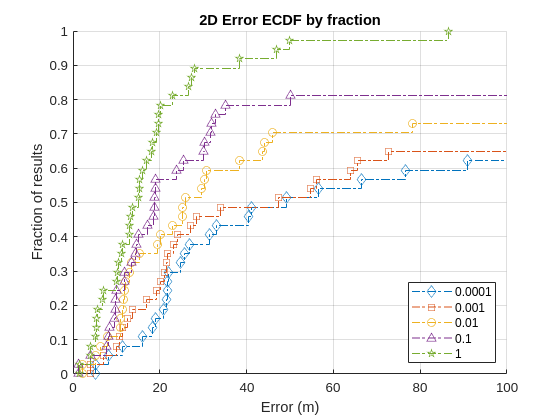

figure();
hold on; grid on;
% flab = cell(ceil(length(fractions)/8),1);
flab = {'0.0001', '0.001', '0.01', '0.1', '1'};
styles = {'d-.', 's-.', 'o-.', '^-.', 'p-.'};
k = 1;
for ii = length(fractions):-1:1
    if mod(ii+2,3) == 0 && ii~=4 && ii~=13
        [f,y] = ecdf(dist(:,ii));
        stairs(y, f, styles{k});
%         flab{k} = num2str(fractions(ii));
        k = k+1;
    end
end
legend(flab,'Location',"southeast");

xlabel('Error (m)');
ylabel('Fraction of results');
title('2D Error ECDF by fraction');
xlim([0,100]);
hold off;

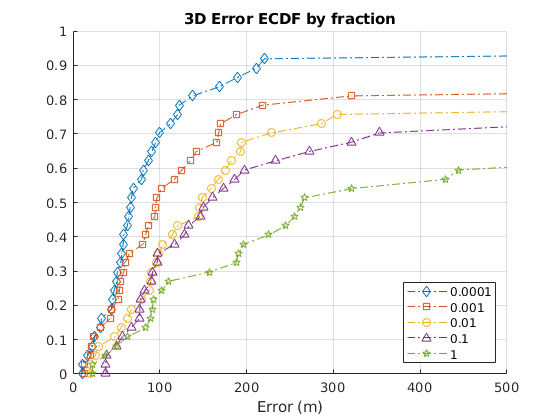

figure();
hold on; grid on;
k = 1;
for ii = 1:length(fractions)
    if mod(ii+2,3) == 0 && ii~=4 && ii~=13
        [f,y]  = ecdf(dist3d(:,ii));
        plot(y, f, styles{k});
        k = k+1;
    end
end
legend(flab,'Location',"southeast");

xlabel('Error (m)');
title('3D Error ECDF by fraction');
xlim([0,500]);
hold off;

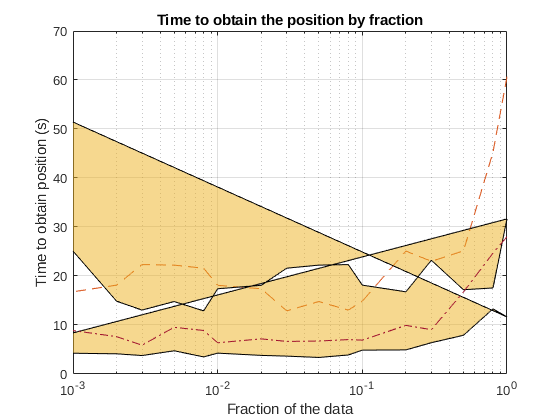

figure();
labels = cell(length(fractions),1);
q25 = zeros(1,length(fractions));
q50 = zeros(1,length(fractions));
q75 = zeros(1,length(fractions));
for ii = 1:length(fractions)
    labels{ii} = num2str(fractions(ii));
    q25(ii) = quantile(time(:,ii),0.25);
    q50(ii) = quantile(time(:,ii),0.50);
    q75(ii) = quantile(time(:,ii),0.75);
end

figure();
semilogx(fractions, q25,'Color',[0.8500, 0.3250, 0.0980],'LineStyle',"--");
hold on; grid on;
semilogx(fractions,q75,'Color',[0.8500, 0.3250, 0.0980],'LineStyle',"--");
f_flip = [fractions; fliplr(fractions)];
d_flip = [q25, fliplr(q75)];
h = fill(f_flip,d_flip,[0.9290, 0.6940, 0.1250]);
alpha(h,0.5);
semilogx(fractions,q50,'Color',[0.6350 0.0780 0.1840],'LineStyle',"-.");
xlim([1e-3,max(fractions)]);
title('Time to obtain the position by fraction');
xlabel('Fraction of the data');
ylabel('Time to obtain position (s)');
hold off;

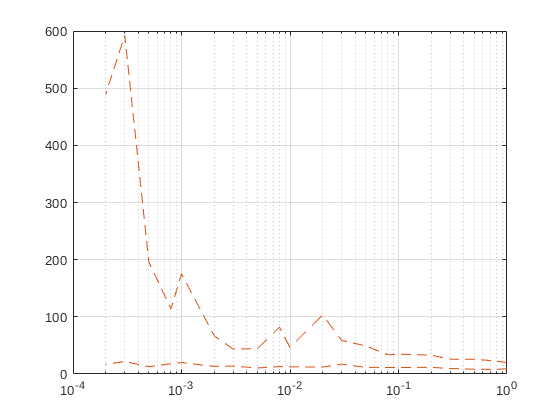

figure();
labels = cell(length(fractions),1);
q25 = zeros(1,length(fractions));
q50 = zeros(1,length(fractions));
q75 = zeros(1,length(fractions));
for ii = 1:length(fractions)
    labels{ii} = num2str(fractions(ii));
    q25(ii) = quantile(dist(:,ii),0.25);
    q50(ii) = quantile(dist(:,ii),0.50);
    q75(ii) = quantile(dist(:,ii),0.75);
end

figure();
semilogx(fractions, q25,'Color',[0.8500, 0.3250, 0.0980],'LineStyle',"--");
hold on; grid on;
semilogx(fractions,q75,'Color',[0.8500, 0.3250, 0.0980],'LineStyle',"--");

f_flip = [fractions, fliplr(fractions)];
d_flip = [q25, fliplr(q75)];
h = fill(f_flip,d_flip,[0.9290, 0.6940, 0.1250]);

Error using fill
Vectors must be the same length.

alpha(h,0.5);
semilogx(fractions,q50,'Color',[0.6350 0.0780 0.1840],'LineStyle',"-.");
xlim([1e-3,max(fractions)]);
title('Localization error by fraction');
xlabel('Fraction of the data');
ylabel('Localizatio error (m)');
hold off;